# Decision Trees: Predictor Importance

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the data.

rng(0)
T = readtable("./data/pumpFeatures.csv")

T = 1000×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean    

This code fits a 5-fold cross-validated classification tree model to the original data and calculates the loss.

mdlFull = fitctree(T, "faultCode", "KFold", 5);
fullLoss = kfoldLoss(mdlFull)

fullLoss = 0.1360

## Task 1

You can use `predictorImportance` on a decision tree model to calculate the importance of each predictor variable.

`predImp` `=` `predictorImportance``(``treeModel``)`

**Note**  You cannot use the `predictorImportance` function with cross-validated decision tree models.

mdl = fitctree(T, "faultCode");
p = predictorImportance(mdl)

p =     0.0032         0         0         0    0.0001    0.0000         0         0    0.0001         0    0.0001    0.0001         0    0.0000         0         0         0    0.0002    0.0001    0.0001         0         0         0         0    0.0008    0.0000         0         0    0.0001    0.0009         0    0.0036    0.0001         0         0         0         0         0    0.0026         0    0.0001    0.0001         0    0.0001         0         0         0         0    0.0001         0


## Task 2

You can determine which predictors to keep by setting a threshold for importance. 

toKeep = p > 0.001;

## Task 3

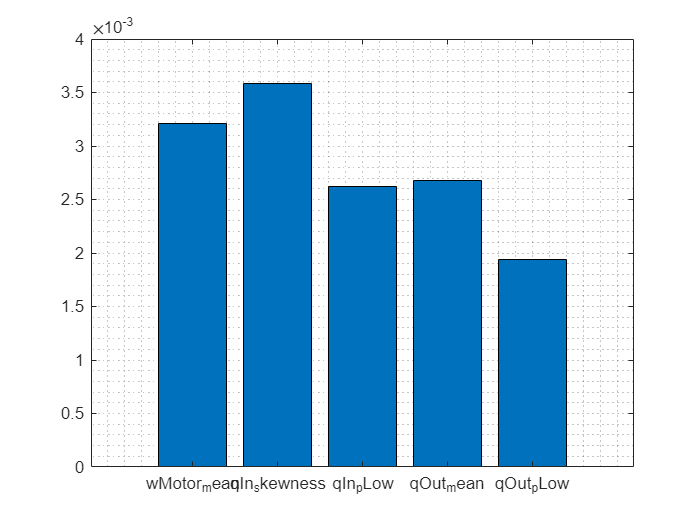

bar(p(toKeep))
grid minor
xticklabels(T.Properties.VariableNames(toKeep))

## Task 4

selected = T(:, [toKeep true])

selected = 1000×6 table
    wMotor_mean    qIn_skewness    qIn_pLow    qOut_mean    qOut_pLow    faultCode
    ___________    ____________    ________    _________    _________    _________

      876.24          1.4468        72.181      35.532        1.3069         0    
      876.24          1.4632        76.301       35.56       0.63792         0    
      876.03          1.4647        68.856      35.561       0.62977         0    
       876.2          1.5033        73.584      35.496       0.56128         0    
       876.2          1.4093        80.285      35.548       0.69665         0    
      876.14          1.4559        76.924      35.549       0.28172         0    
      876.14          1.4711        70.414      35.529       0.46097         0    
      876.26          1.

## Task 5

mdlPart = fitctree(selected, "faultCode", "KFold", 5);
partLoss = kfoldLoss(mdlPart)

partLoss = 0.0910